# .1CWK50 submission

Full instructions on how to submit this live script are available in the assignment specification on Moodle ("How to submit your work" section). Make sure you read them carefully, and that you test your final submission thoroughly before uploading it to Moodle. No additional files can be accepted after the deadline has passed.

## 1. Dataset preparation (20%)

% check the dataset is present:
if ~exist('moons.csv', 'file')
    error('You need to download moons.csv from Moodle and place it into the same directory as this live script');
end

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:

% read in the dataset:
data = readcell('moons.csv');

% have a look at the first 10 rows, and check we can spot the target feature values:
data(1:1:10, 1:1:end)

ans = 10×3 cell array
    {'Feature 1'}    {'Feature 2'}    {'Label'  }
    {[   0.1567]}    {[   1.3182]}    {'Class A'}
    {[  -0.9705]}    {[   0.6211]}    {'Class A'}
    {[  -0.9086]}    {[   0.1598]}    {'Class A'}
    {[   0.7076]}    {[   0.2604]}    {'Class A'}
    {[  -1.2325]}    {[   0.9279]}    {'Class A'}
    {[  -0.6282]}    {[   0.8368]}    {'Class A'}
    {[   0.6124]}    {[   0.2656]}    {'Class A'}
    {[  -0.7009]}    {[  -0.0706]}    {'Class A'}
    {[   1.2655]}    {[   1.3637]}    {'Class A'}



% read out the observations (while dropping the feature names):
obs = data(2:end,:);

% shuffle the observations to remove any ordering:
obs_shuffled = obs(randperm(size(obs,1)), :);

% we'll use 40% of them in our testing data
nTest = round(0.4 * size(obs_shuffled,1))

nTest = 60


% horizontal split...

% copy out our testing observations (first 40% of the data)...:
obs_test = obs_shuffled(1:1:nTest, :);
% ...and our training observations (final 60% of the data):
obs_train = obs_shuffled(nTest+1:1:end, :);

% set the column index of the target feature values (identified visually,
% from the earlier output):
label_index = 3;

% vertical split 1:

% separate the examples and the labels for the testing observations:
test_labels = categorical(obs_test(:, label_index)); %storing all of 3rd column into test_labels
test_examples = cell2mat(obs_test(:, 1:end~=label_index)); %storing everything except 3rd column into test_examples

% have a quick look at the sizes, as a sanity check
size(test_examples)

ans =     60     2


size(test_labels)

ans =     60     1



% vertical split 2:

train_labels = categorical(obs_train(:, label_index)); %doing same thing for training labels
train_examples = cell2mat(obs_train(:, 1:end~=label_index)); %doing same thing for training labels

% have a quick look at the sizes, as a sanity check
size(train_examples)

ans =     90     2


size(train_labels)

ans =     90     1


## 2. Feature space visualisation (20%)

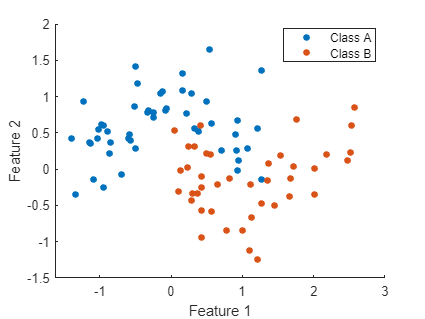

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:
figure; % open a new figure window, ready for plotting
hold('on');

gscatter(train_examples(:,1), train_examples(:,2), train_labels) %Plotting the training data
xlabel('Feature 1'); %labelling the graph
ylabel('Feature 2');

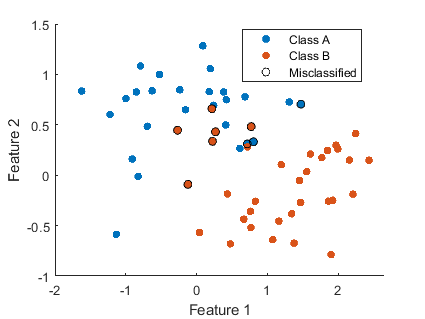


%Training built-in naive bayes classifier using training data
m_nb = fitcnb(train_examples, train_labels);

figure; hold('on');
gscatter(test_examples(:,1), test_examples(:,2), test_labels) %Plotting the predicted testing data
xlabel('Feature 1'); %labelling the graph
ylabel('Feature 2');


% use the naive Bayes classifier to make predictions based on our testing examples:
predictions = m_nb.predict(test_examples);
%1s for no matches and zeros for matches
no_nb = predictions ~= test_labels;
%Prints circle where no_knn is 1 i.e no matches
scatter(test_examples(no_nb,1), test_examples(no_nb,2), 'black', 'DisplayName', 'Misclassified'); 

## 3. Abstraction visualisations (20%)

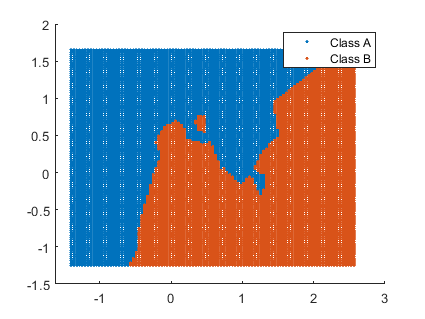

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:

%k-NN classifier using k=1 
m_knn1 = fitcknn(train_examples, train_labels, 'NumNeighbors', 1);
visualise_abstraction(m_knn1, train_examples);   

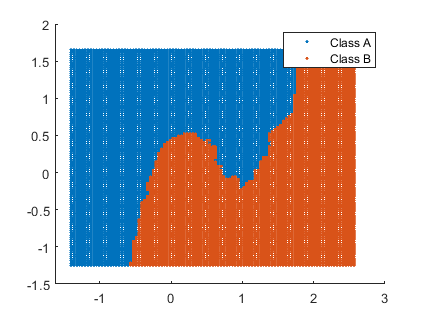


%k-NN classifier using k=5
m_knn5 = fitcknn(train_examples, train_labels, 'NumNeighbors', 5);
visualise_abstraction(m_knn5, train_examples); 

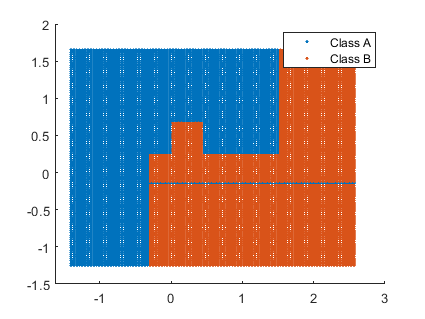


%DT classifier using a minimum parent size of 10, no merging, no pruning
m_dt10 = fitctree(train_examples, train_labels, 'MergeLeaves', 'off', 'Prune', 'off', 'MinParentSize', 10);
visualise_abstraction(m_dt10, train_examples); 

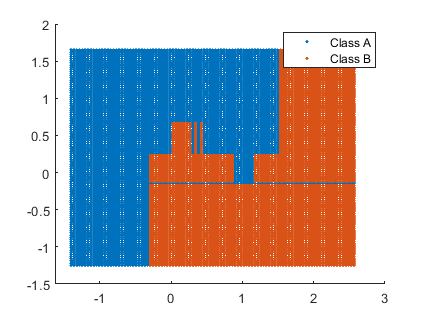


%DT classifier using a minimum parent size of 1, no merging, no pruning
m_dt1 = fitctree(train_examples, train_labels, 'MergeLeaves', 'off', 'Prune', 'off', 'MinParentSize', 1);
visualise_abstraction(m_dt1, train_examples); 

## 4. Classifier re-implementations (20%)

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:

%k-NN classifier using k=1 
mym_knn1 = my_fitcknn(train_examples, train_labels, 'NumNeighbors', 1);
visualise_abstraction(mym_knn1, train_examples);   


%k-NN classifier using k=5
mym_knn5 = my_fitcknn(train_examples, train_labels, 'NumNeighbors', 5);
visualise_abstraction(mym_knn5, train_examples); 


%%%%%% DT My classification%%%%%%%

% MINIMUN PARENT SIZE 10
mym_dt10 = my_fitctree(train_examples, train_labels, 'MinParentSize', 10, 'MaxNumSplits', 15, 'Verbose', false);
visualise_abstraction(mym_dt10, train_examples); 


% MINIMUM PARENT SIZE 1
mym_dt1 = my_fitctree(train_examples, train_labels, 'MinParentSize', 1, 'MaxNumSplits', 15, 'Verbose', false);
visualise_abstraction(mym_dt1, train_examples); 



%view trees
% mym_dt10.view(mym_dt10.root)
% mym_dt1.view(mym_dt1.root)

## 5. Extension to ensembles (20%)

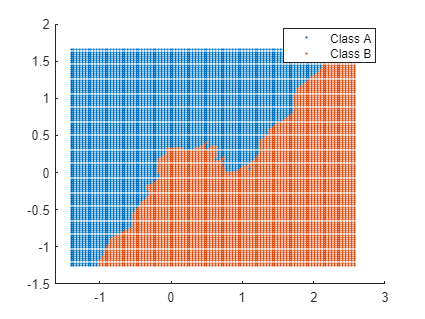

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:


%NB and KNN
my_en1 = my_fitcensemble1(train_examples,train_labels, 'Verbose', false);
visualise_abstraction(my_en1, train_examples);

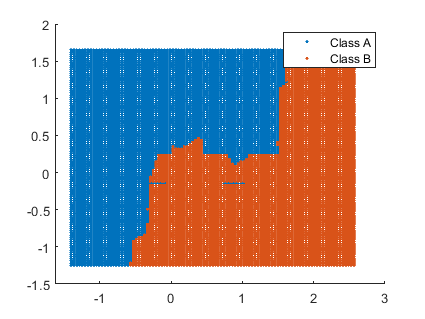



%NB, KNN and DT
my_en2 = my_fitcensemble2(train_examples,train_labels, 'Verbose', false);
visualise_abstraction(my_en2, train_examples);

**Extra**

%% reducing examples to 2d space to visualise and reducing testing examples to 2d space for predictions

% check the dataset is present:
if ~exist('iris.csv', 'file')
    error('You need to download iris.csv from Moodle and place it into the same directory as this live script');
end

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:

% read in the dataset:
data = readcell('iris.csv');

% have a look at the first 10 rows, and check we can spot the target feature values:
data(1:1:10, 1:1:end)

ans = 10×5 cell array
    {'sepal_length'}    {'sepal_width'}    {'petal_length'}    {'petal_width'}    {'species'}
    {[      5.1000]}    {[     3.5000]}    {[      1.4000]}    {[     0.2000]}    {'setosa' }
    {[      4.9000]}    {[          3]}    {[      1.4000]}    {[     0.2000]}    {'setosa' }
    {[      4.7000]}    {[     3.2000]}    {[      1.3000]}    {[     0.2000]}    {'setosa' }
    {[      4.6000]}    {[     3.1000]}    {[      1.5000]}    {[     0.2000]}    {'setosa' }
    {[           5]}    {[     3.6000]}    {[      1.4000]}    {[     0.2000]}    {'setosa' }
    {[      5.4000]}    {[     3.9000]}    {[      1.7000]}    {[     0.4000]}    {'setosa' }
    {[      4.6000]}    {[     3.4000]}    {[      1.4000]}    {[     0.3000]}    {'setosa' }
    {[           5]}    {[     3.4000]}    {[      1.5000]}    {[     0.2000]}    {'setosa' }
    {[      4.4000]}    {[     2.9000]}    {[      1.4000]}    {[     0.2000]}    {'setosa' }



% read out the observations (while dropping the feature names):
obs = data(2:end,:);

% shuffle the observations to remove any ordering:
obs_shuffled = obs(randperm(size(obs,1)), :);

% we'll use 40% of them in our testing data
nTest = round(0.4 * size(obs_shuffled,1))

nTest = 60


% horizontal split...

% copy out our testing observations (first 40% of the data)...:
obs_test = obs_shuffled(1:1:nTest, :);
% ...and our training observations (final 60% of the data):
obs_train = obs_shuffled(nTest+1:1:end, :);

% set the column index of the target feature values (identified visually,
% from the earlier output):
label_index = 5;

% vertical split 1:

% separate the examples and the labels for the testing observations:
test_labels = categorical(obs_test(:, label_index)); %storing all of 3rd column into test_labels
test_examples = cell2mat(obs_test(:, 1:end~=label_index)); %storing everything except 3rd column into test_examples

% have a quick look at the sizes, as a sanity check
size(test_examples)

ans =     60     4


size(test_labels)

ans =     60     1



% vertical split 2:

train_labels = categorical(obs_train(:, label_index)); %doing same thing for training labels
train_examples = cell2mat(obs_train(:, 1:end~=label_index)); %doing same thing for training labels

% have a quick look at the sizes, as a sanity check
size(train_examples)

ans =     90     4


size(train_labels)

ans =     90     1


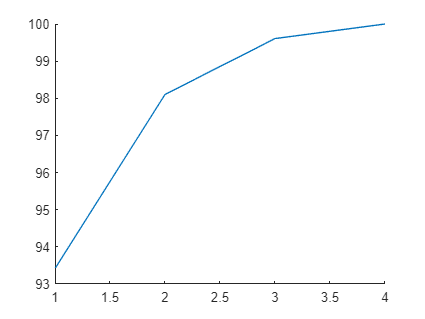


%Reduce Train_exampels to a new 2d feature space also showing variance
[reduced_train, mean_train, train_PCA] = PCA(train_examples); 

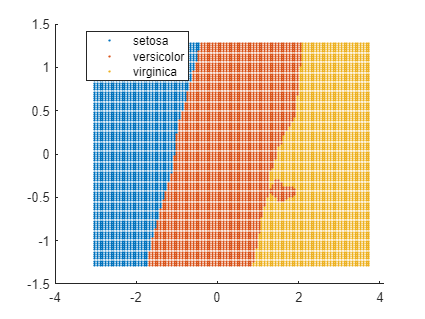

%training classifier on this reduced feature space and visualising
my_knn = my_fitcknn(reduced_train, train_labels);
visualise_abstraction(my_knn, reduced_train);



%center test data using the mean of training data
centered_test_examples = (test_examples - (repmat(mean_train, [size(test_examples,1) 1])));

%project this test data onto the new plane using PCA of train examples
my_test_data_transformed = centered_test_examples * train_PCA;
%reduce dimensions
my_test_data_transformed = my_test_data_transformed(:,1:2);

%Predict and measure accuracy
predictions = my_knn.predict(my_test_data_transformed);
p_knn = sum(predictions == test_labels) / length(test_labels)

p_knn = 0.9500

**Extra**

%% Neural net to get predictions

%Preparing validation data
valid = cell(2,1);
valid{1} = test_examples;
valid{2} = test_labels;

%training the net
net = fitcnet(train_examples, train_labels, 'LayerSizes',[25 20], 'Activations','relu', 'Verbose',1, 'ValidationData',valid);

|==========================================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  | Validation | Validation |
|            |            |            |            | Time (sec) | Loss       | Checks     |
|==========================================================================================|
|           1|    0.377987|    0.324043|    0.353678|    0.022630|    0.376079|           0|
|           2|    0.341412|    0.068803|    0.117791|    0.010866|    0.341485|           0|
|           3|    0.333804|    0.069882|    0.051371|    0.013179|    0.333954|           0|
|           4|    0.277608|    0.161044|    0.652764|    0.005384|    0.277535|           0|
|           5|    0.212075|    0.173979|    0.576286|    0.010250|    0.210481|           0|
|           6|    0.132382|    0.448913|    2.110542|    0.002720|    0.127976|           0|
|           7|    0.113398|    0.414942|    0.454231|    0.000829|    

getVerbose = net.TrainingHistory;

%Best performance validation loss
perform = [];
getVerbose = getVerbose{:,:}; %convert to table to matrix
validation_loss = getVerbose(:,6);
perform(end+1,1) = validation_loss(end-6,1);

%Get the prediced class memberships for the training and testing data
 pred_train_labels = predict(net,train_examples);
 pred_test_labels = predict(net,test_examples);
 
%Get the confusion matrices
[confusion_train,~] = confusionmat(train_labels, pred_train_labels);
[confusion_test,~] = confusionmat(test_labels, pred_test_labels);

disp('Training accuracy');

Training accuracy


disp(sum(diag(confusion_train))/sum(sum(confusion_train)));

    0.9778




disp('Testing accuracy');

Testing accuracy


disp(sum(diag(confusion_test))/sum(sum(confusion_test)));

     1

